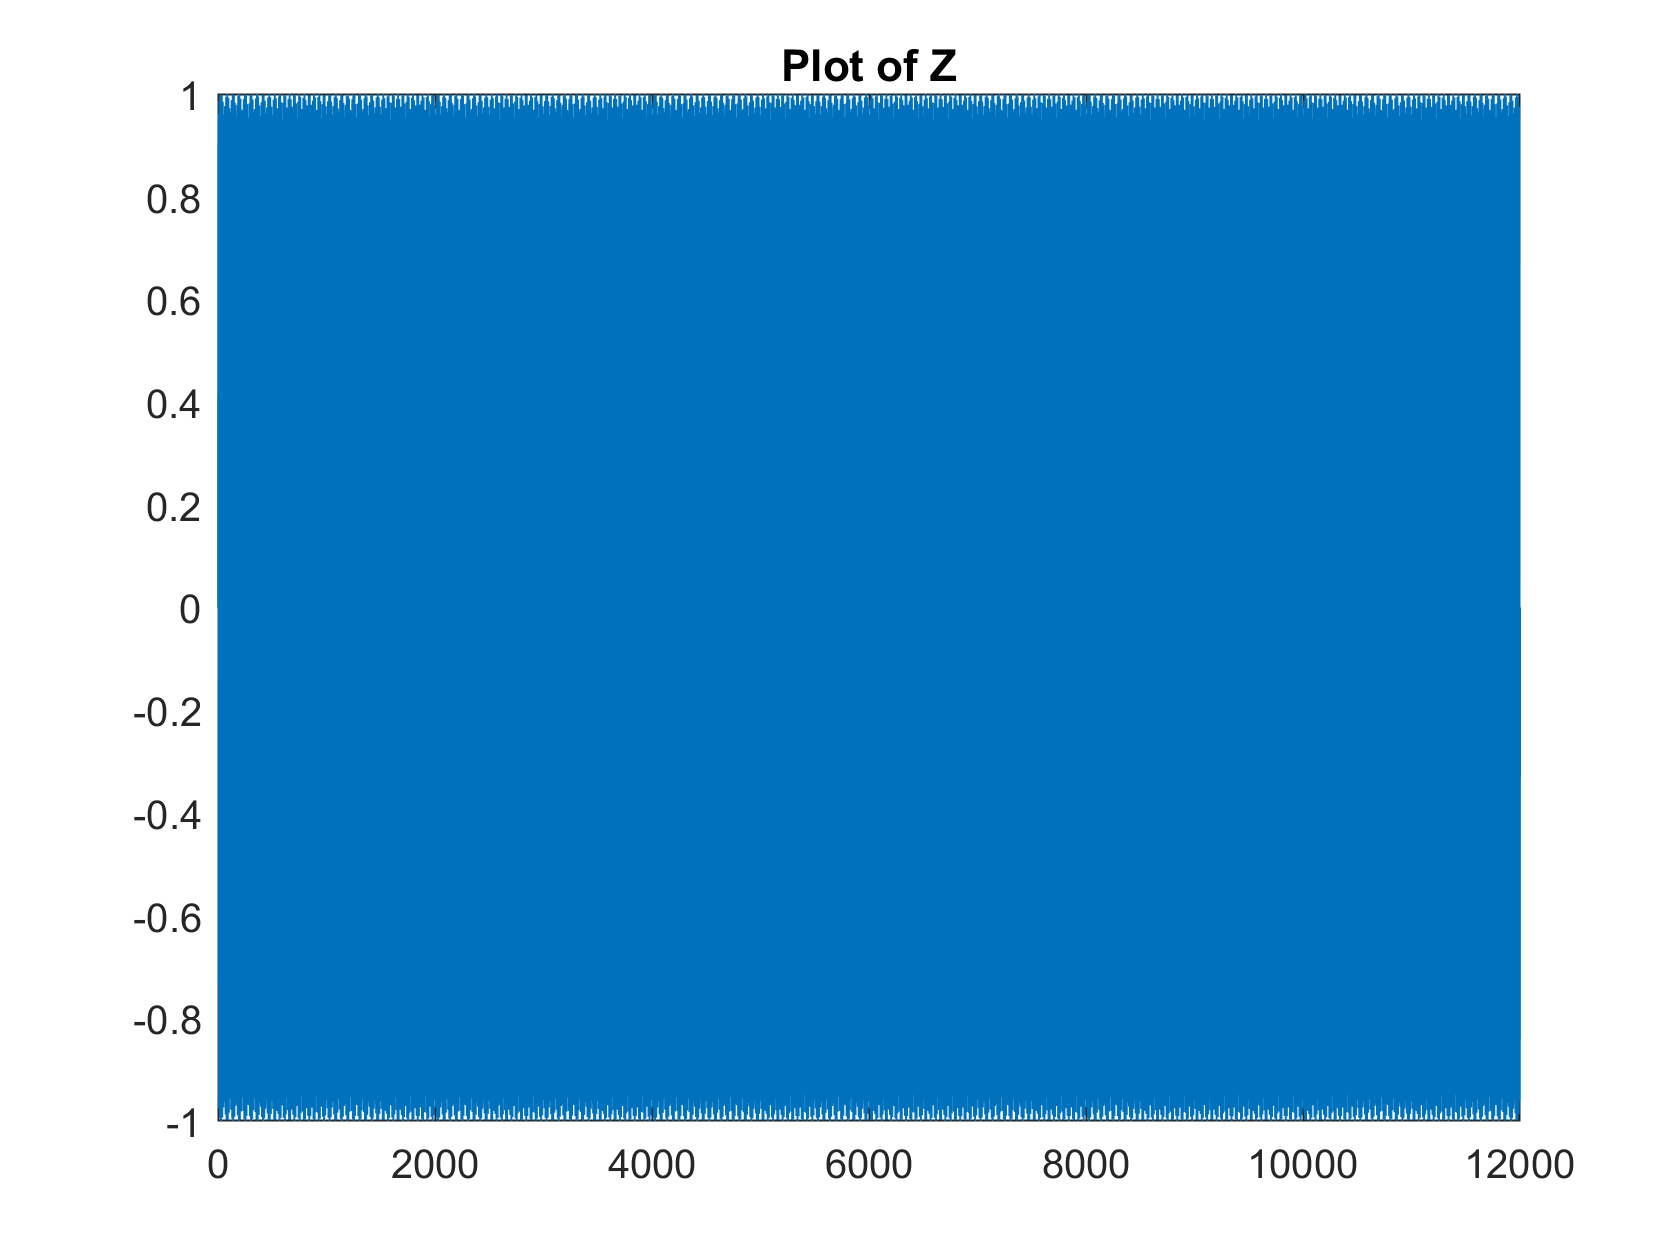

%ee432 FSK lab
%Lab 9 
clear
Tb = 0.1; %10 bits per second
Ns = 500; %Number of samples per bit
fc = 500; %Carrier Frequency is 500Hz
df = 10;
x = linspace(0,Tb,Ns);
f0 = fc-df; %490 Hz
f1 = fc+df; %510 Hz
s0 = sin(2*pi*f0*x);%logic 0 signal
s1 = sin(2*pi*f1*x); %logic 1 signal
synch = [ s0 s1 s0 s1 s0 s1 s0 s1 ]; %known sync pattern 
%at the start of the data (500 samples in each ntrval)
data = [ s0 s0 s1 s0 s1 s1 s0 s1 s0 s1 s1 s1 s1 s0 s1 s0 ];
%data is known 
z = [ synch data ]; %received sequence
plot(z)
title("Plot of Z")

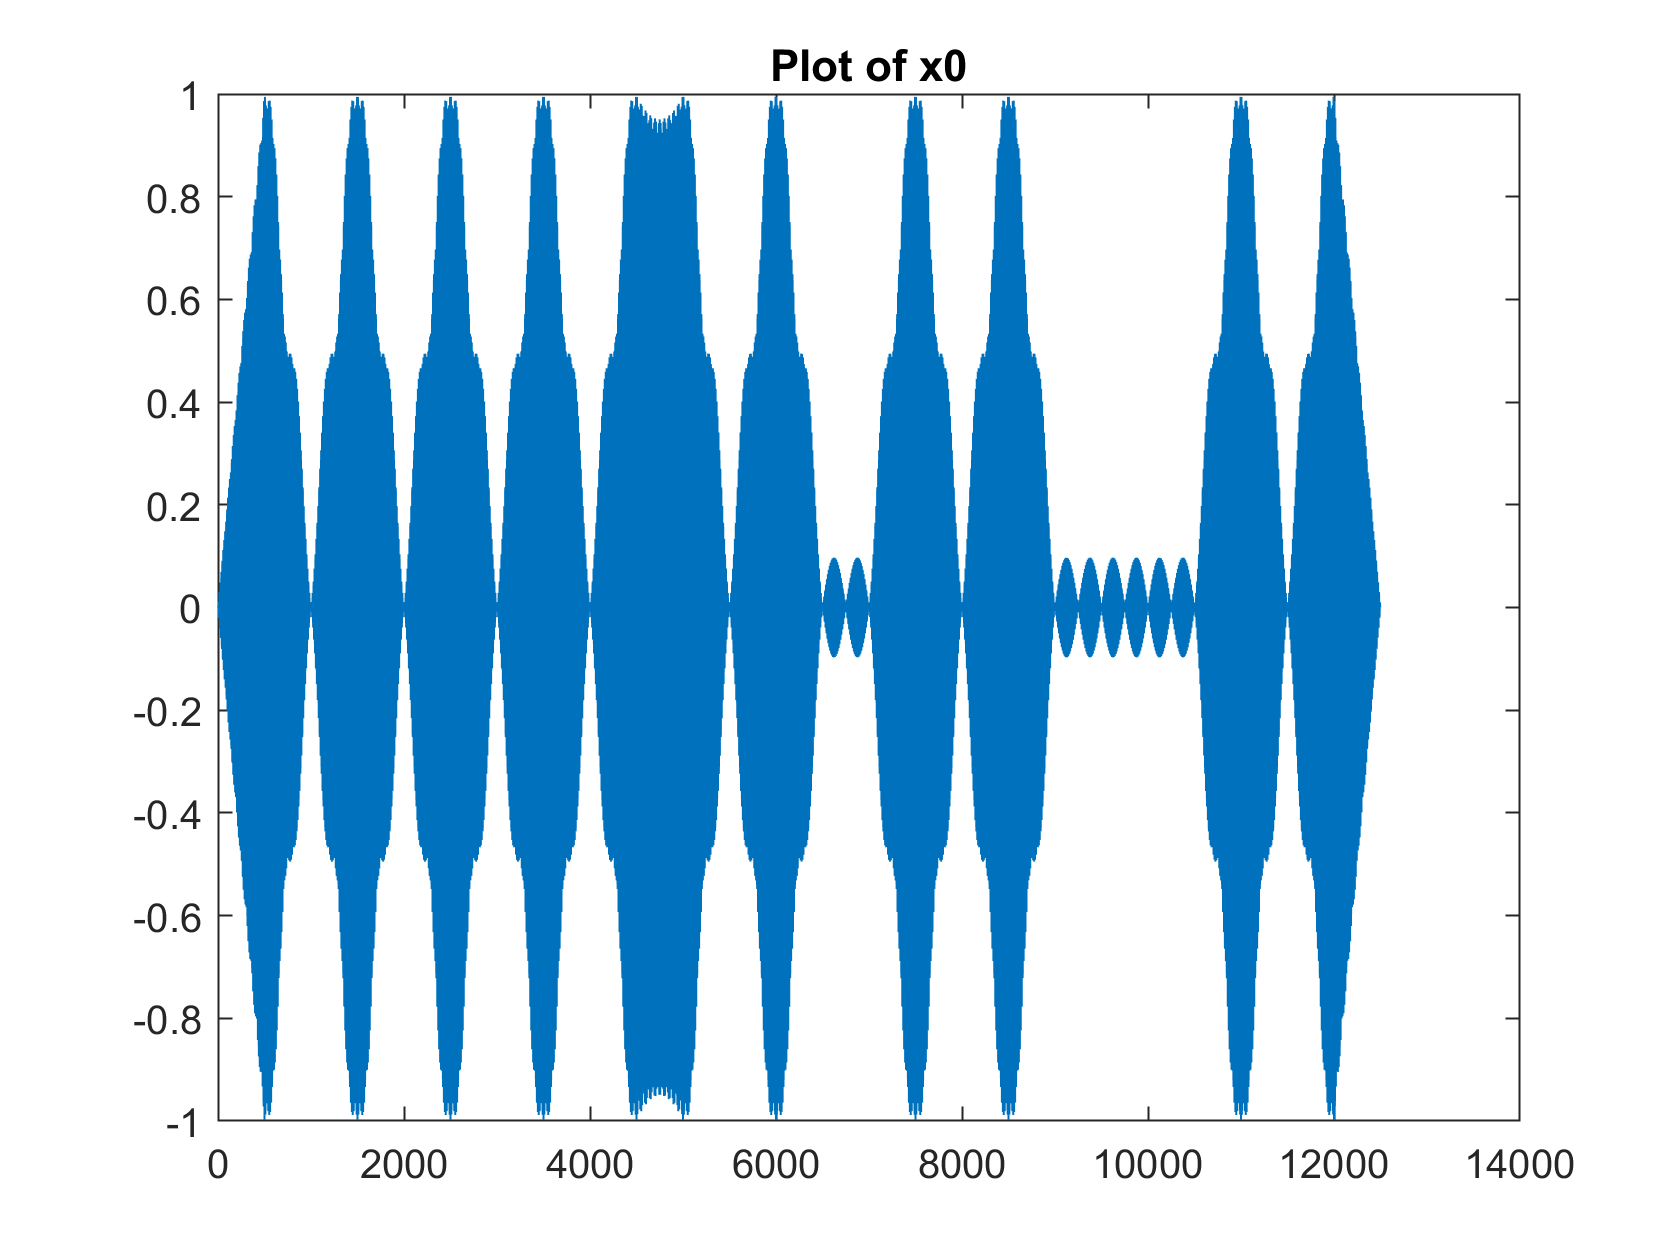

%concatonate the sync sequence followed by data 
%waveform sequence

%sound(z,5000);

%Received

%Matched Filter Design
x0 = (2/Ns)*conv(z, s0);
plot(x0)
title("Plot of x0")

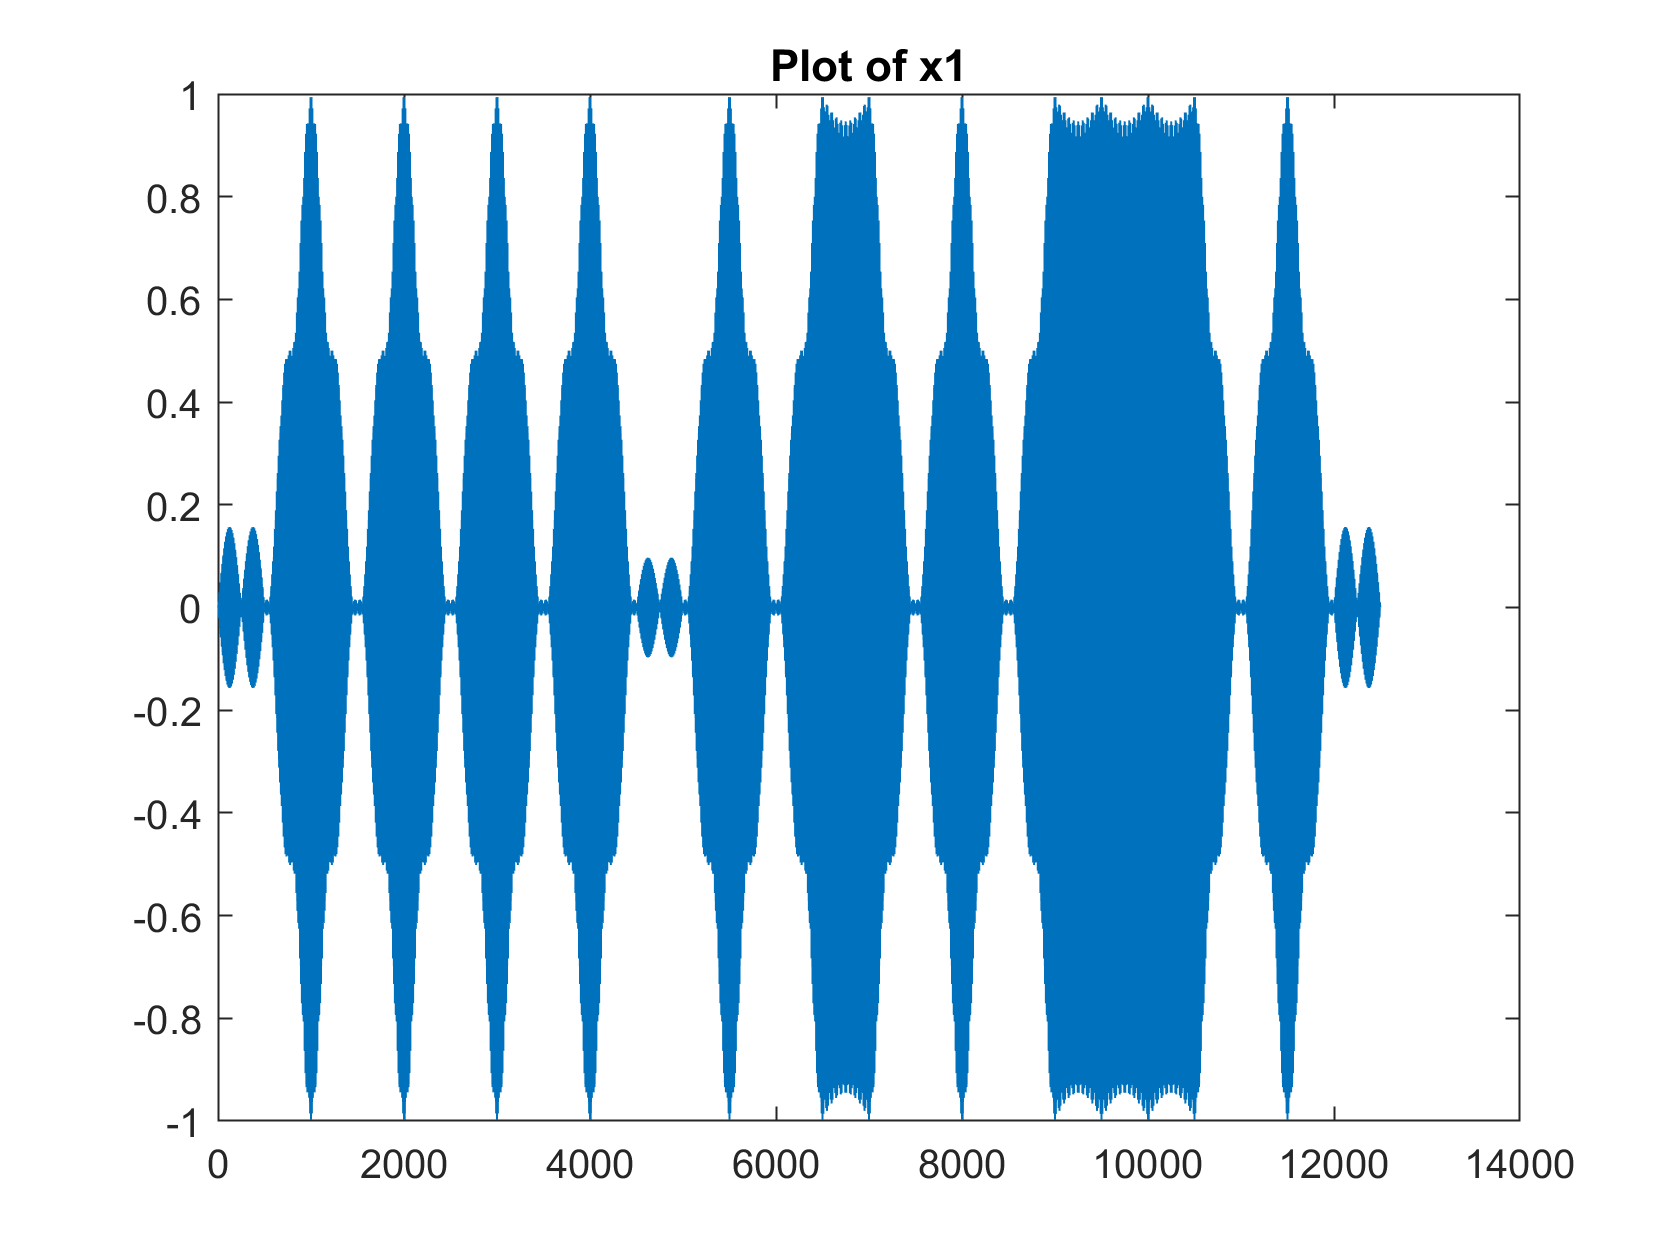

x1 = (2/Ns)*conv(z, s1);
plot(x1)
title("Plot of x1")

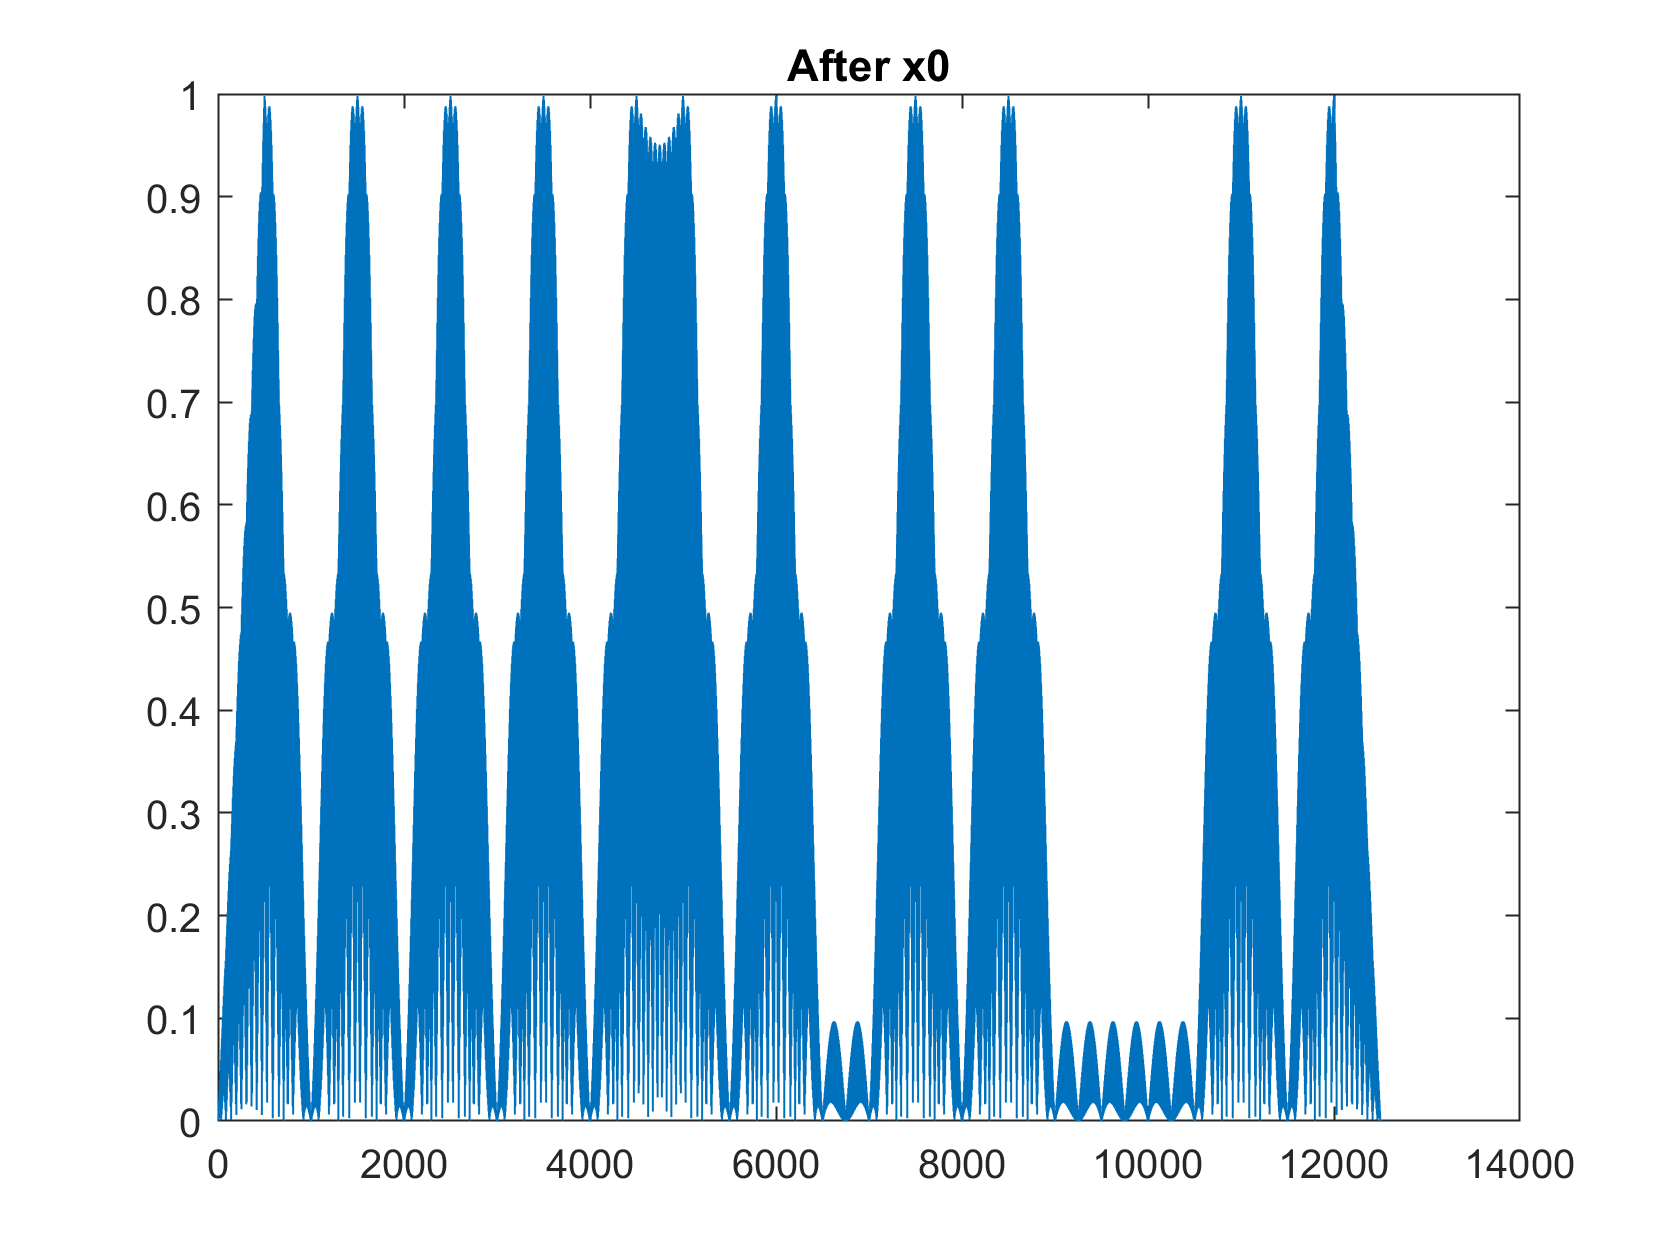


%Envelope Detector
%rectify each signal 
x0 = abs(x0);
plot(x0)
title('After x0')

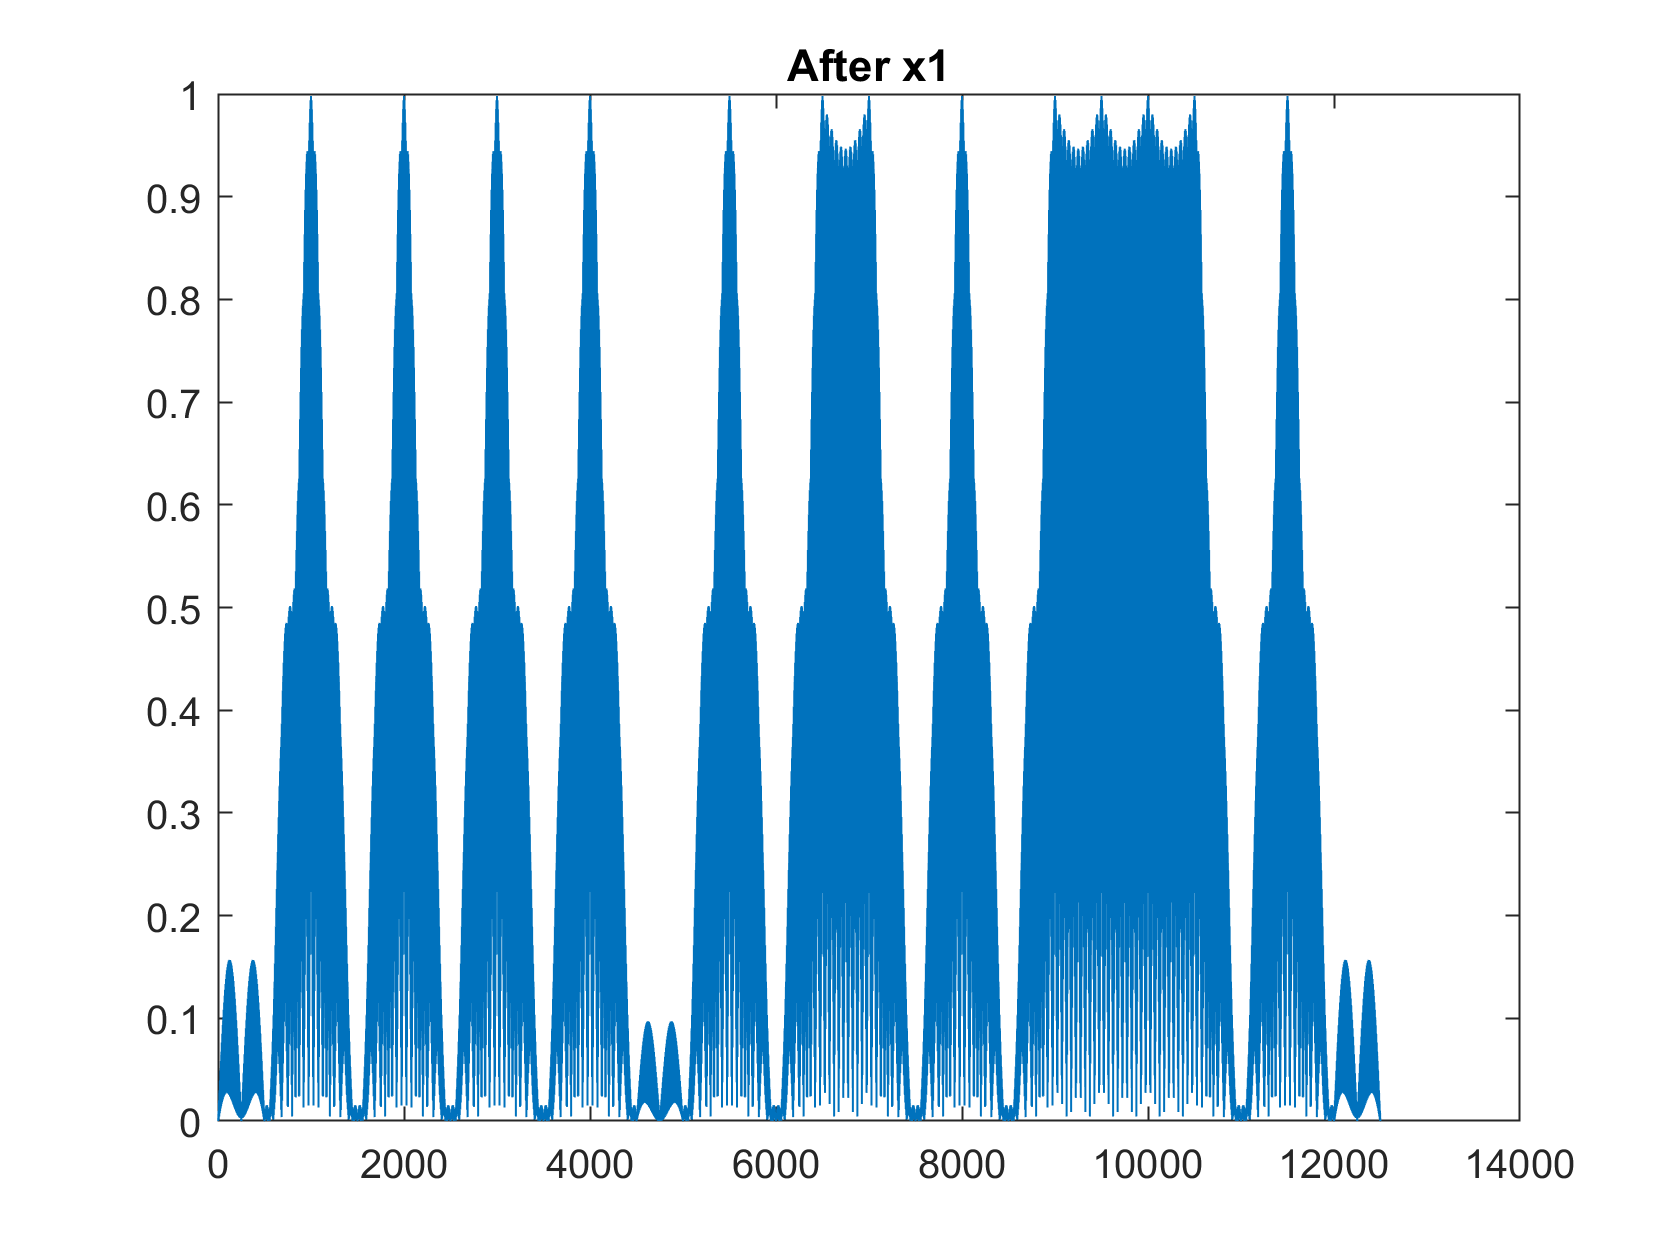

x1 = abs(x1);
plot(x1)
title('After x1')

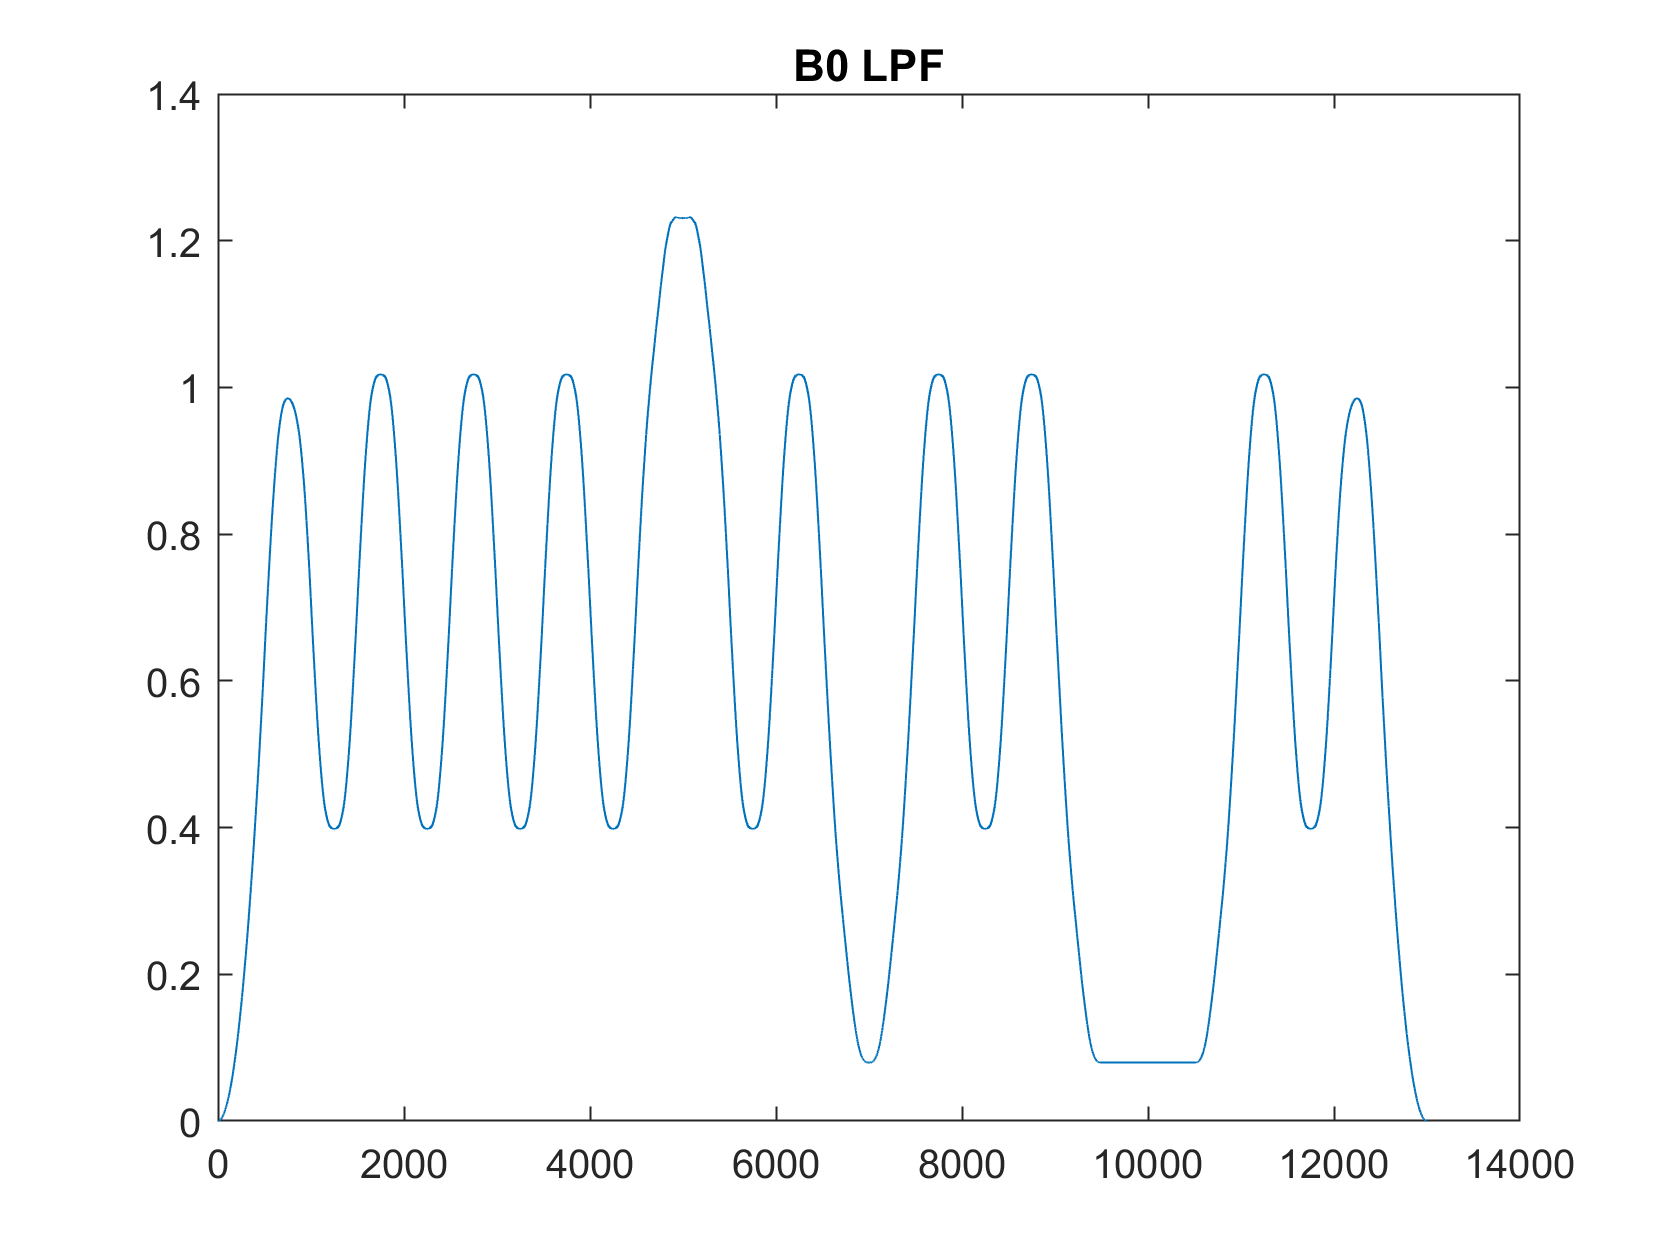


%LPF
b0 = conv(x0, (2/Ns)*ones(1,Ns));
plot(b0)
title('B0 LPF')

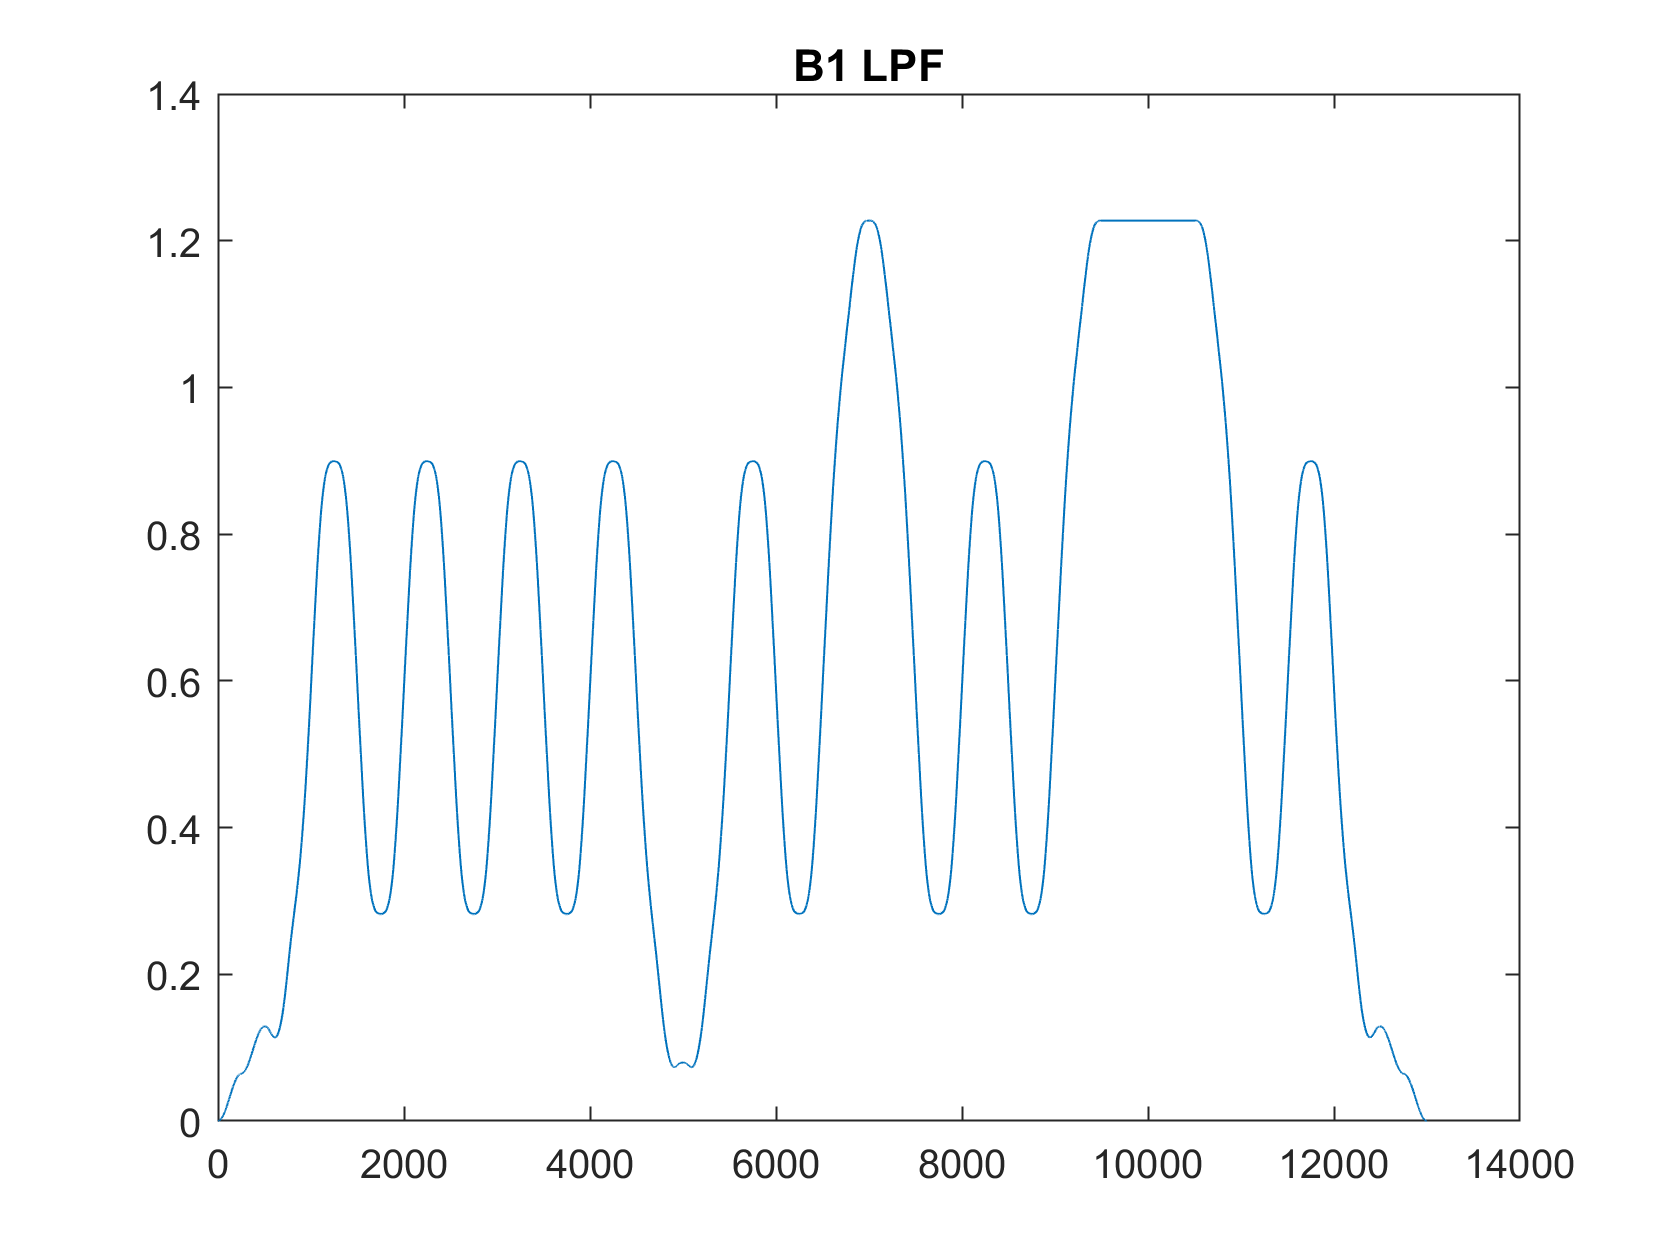

b1 = conv(x1, (2/Ns)*ones(1,Ns));
plot(b1)
title('B1 LPF')

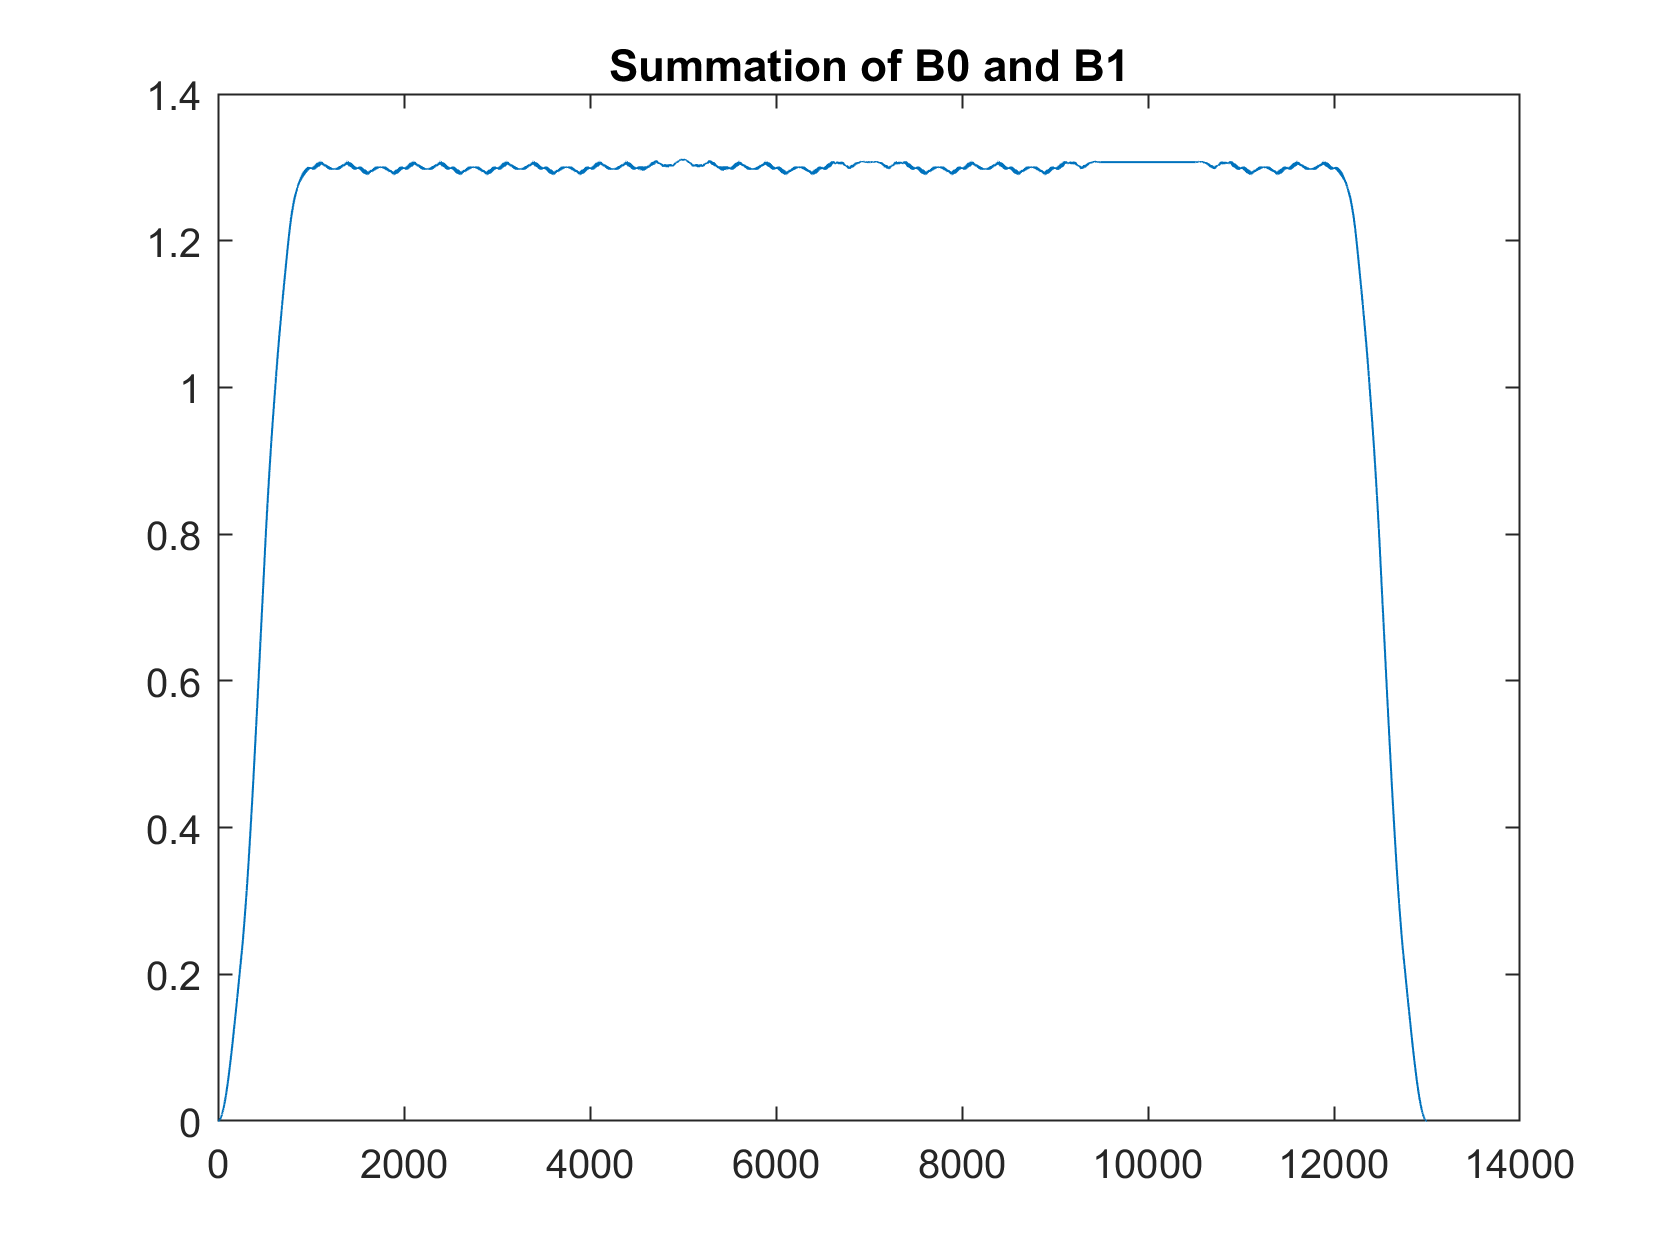


b_gammaselector = b1+b0;


plot(b_gammaselector)
title('Summation of B0 and B1')

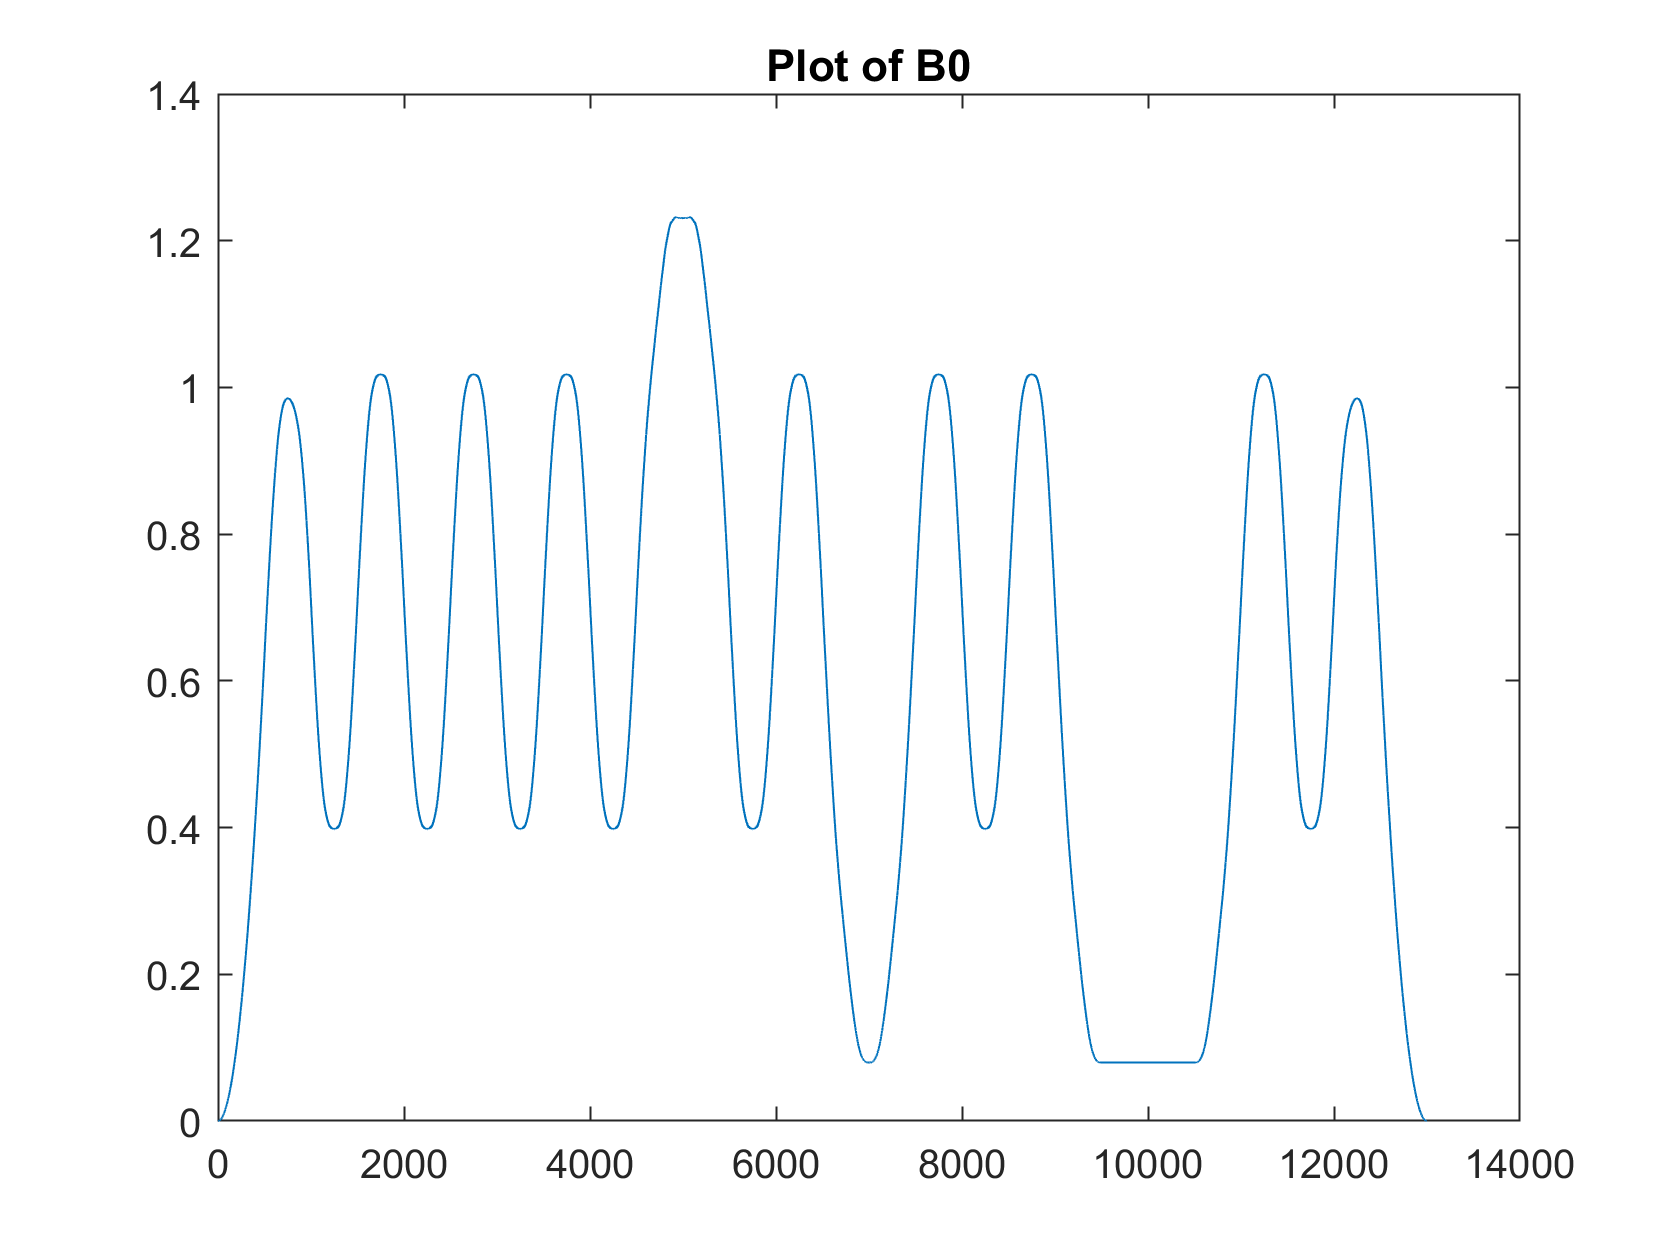

plot(b0)
title("Plot of B0")

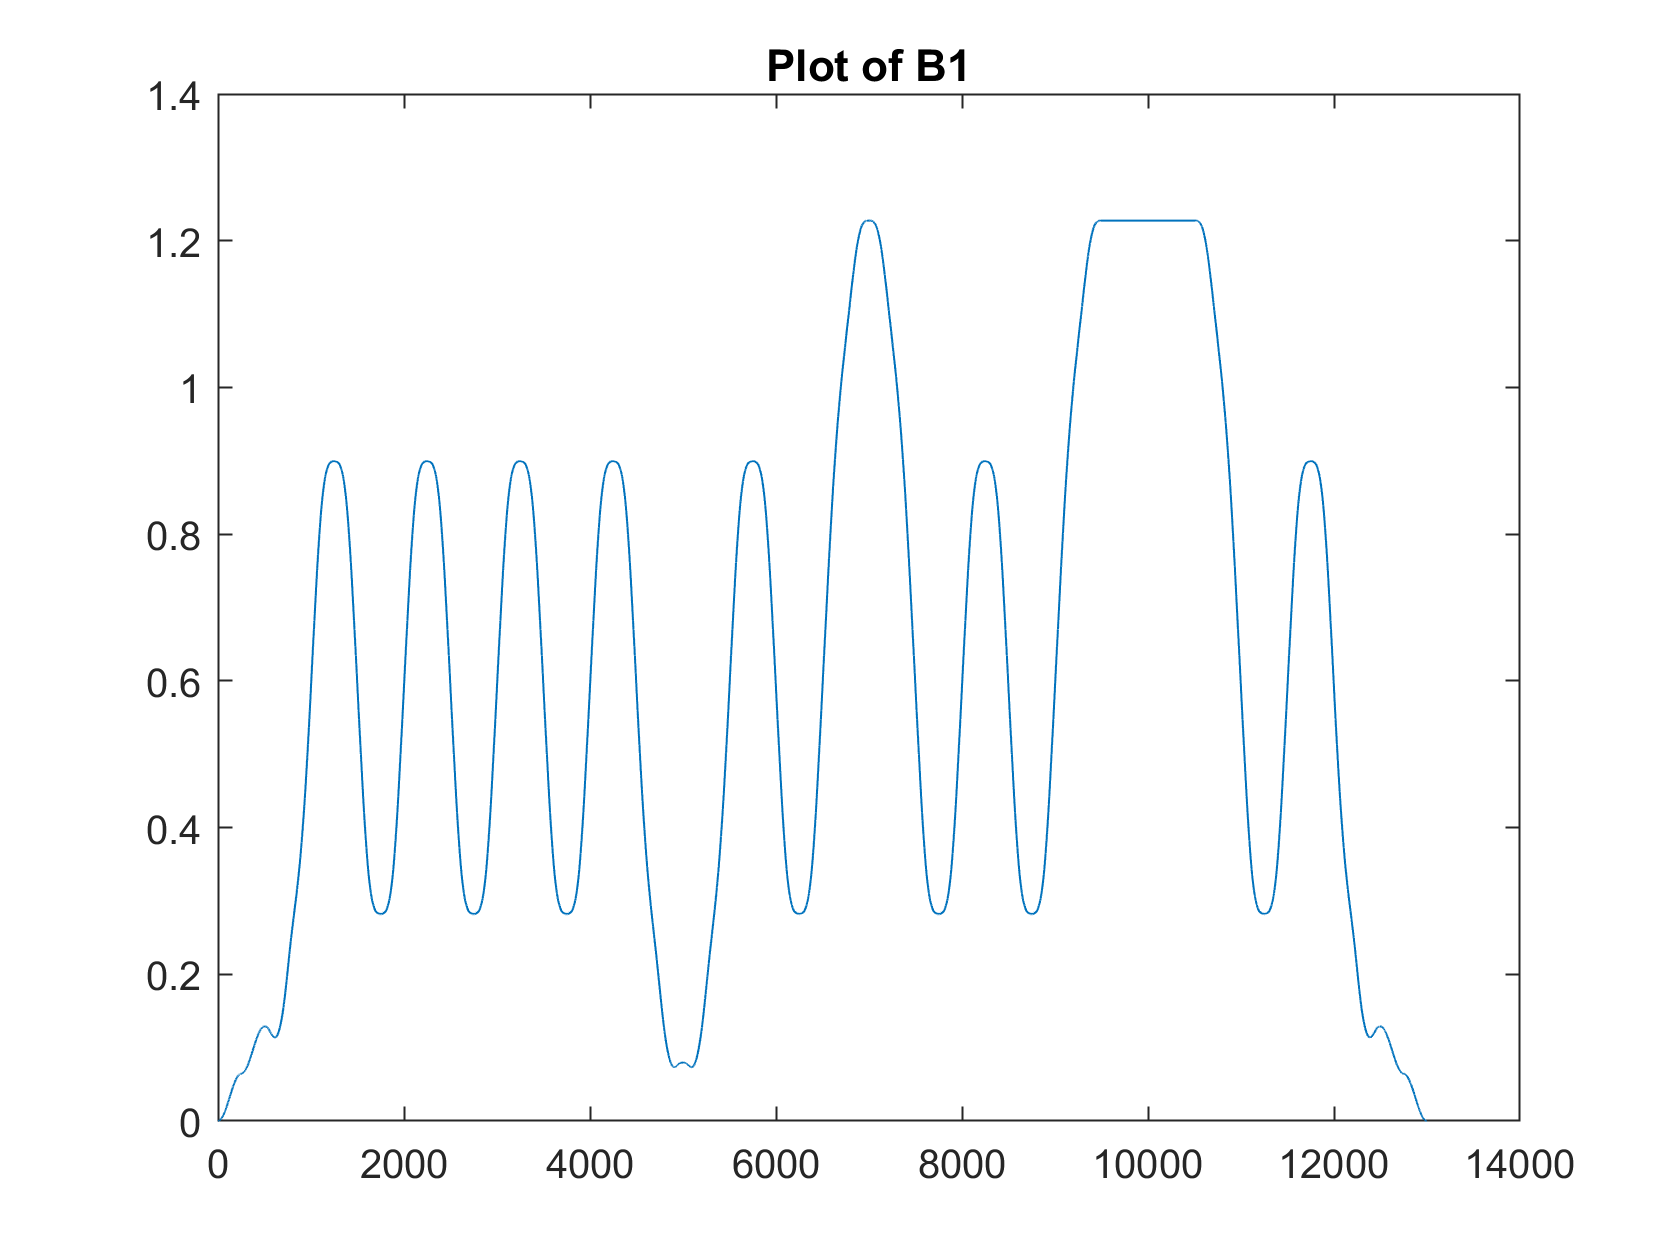

%Summation of these sequences
b0 = (-1*b0);

plot(b1)
title("Plot of B1")

b = b0 + b1;

b =          0         0    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000    0.0001    0.0001    0.0000   -0.0001   -0.0000    0.0001    0.0001   -0.0000   -0.0002   -0.0001    0.0000    0.0001   -0.0000   -0.0002   -0.0002   -0.0000


plot(b)
gamma = .65 %I just chose this because it was close

gamma = 0.6500

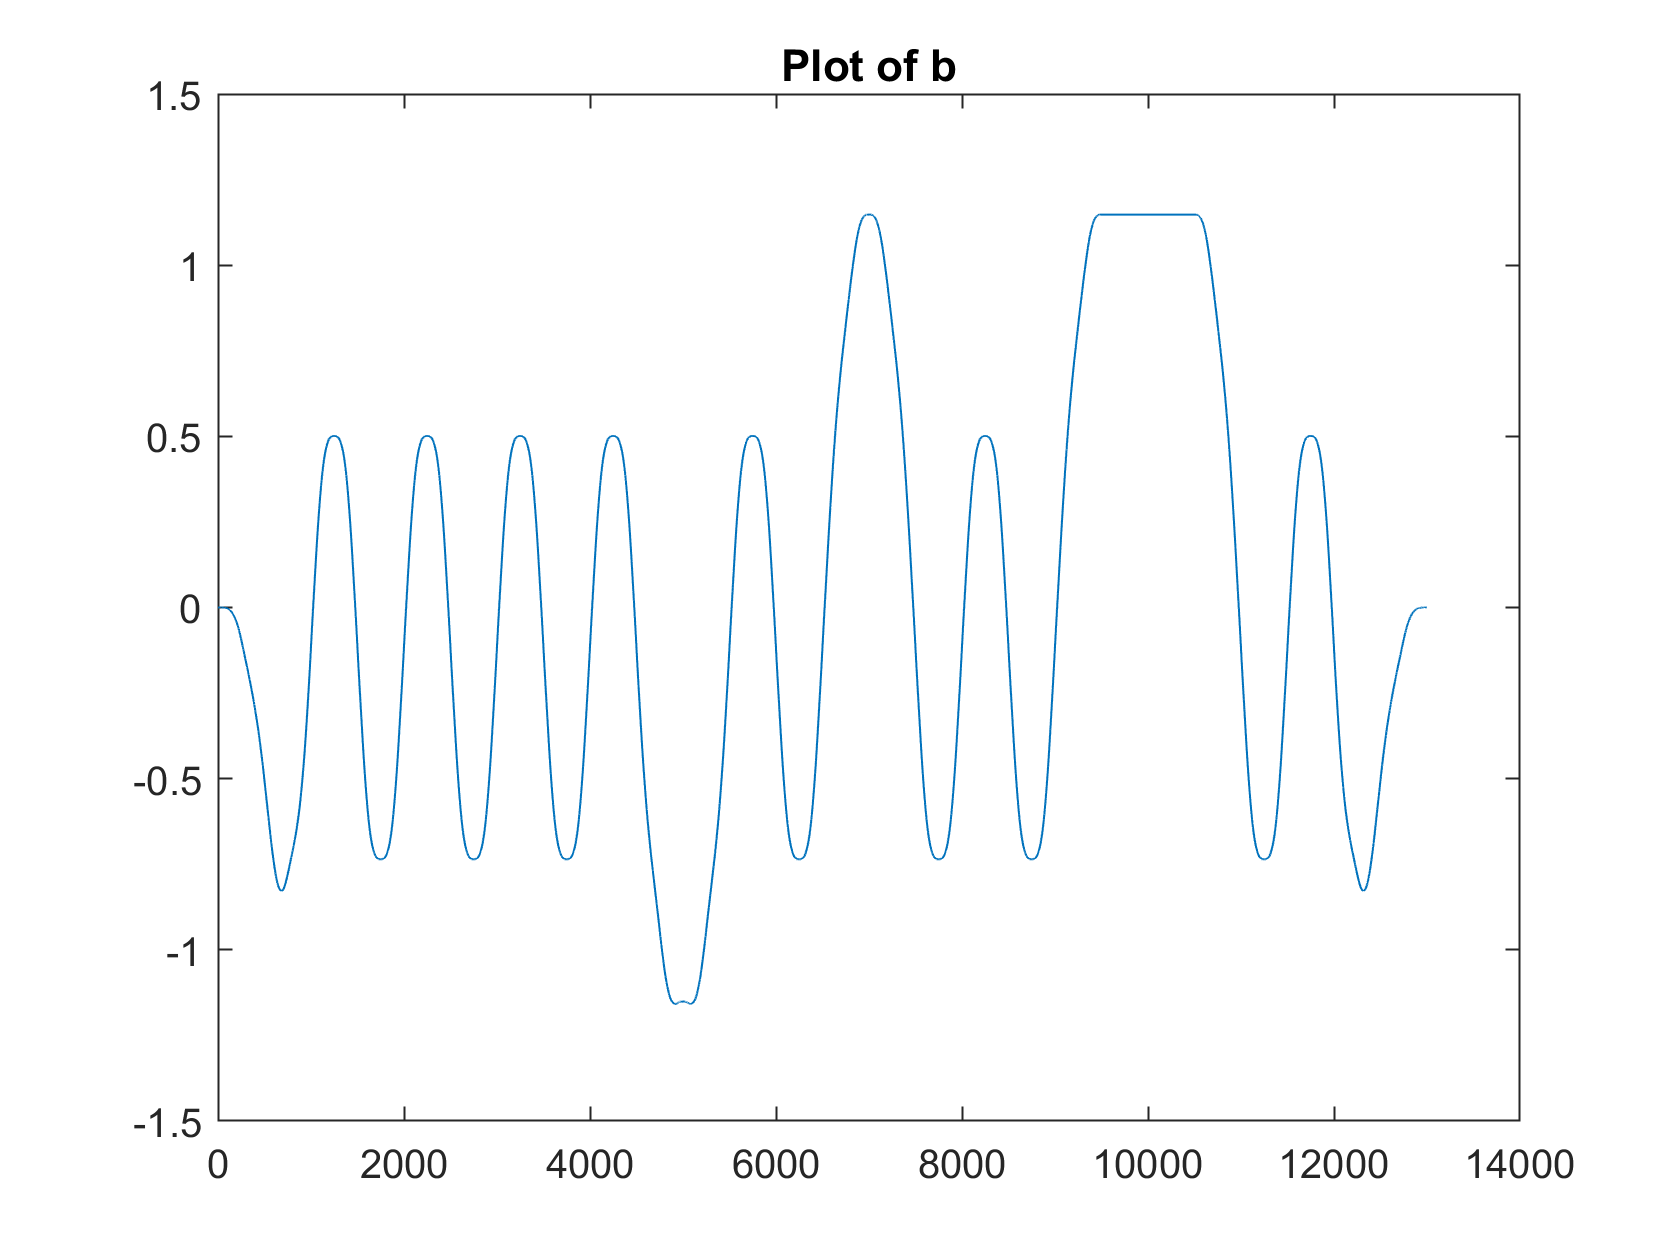

%to the first peak of actual data lol
title("Plot of b")


%Sign and level shifter
bhat = zeros(1, length(b));
for i = 1:length(b)
    if (b(i) > 0)
        bhat(i) = 1;
    elseif (b(i) == 0)
        bhat(i) = 0;
    else 
        bhat(i) = 0;
    end
end
bhat;

bhat =      0     0     1     1     1     1     0     0     0     1     1     0     0     0     1     1     0     0     0     1     1     0     0     0     1     1     0     0     0     1     1     0     0     0     1     1     1     0     0     1     1     0     0     0     1     1     0     0     0     0


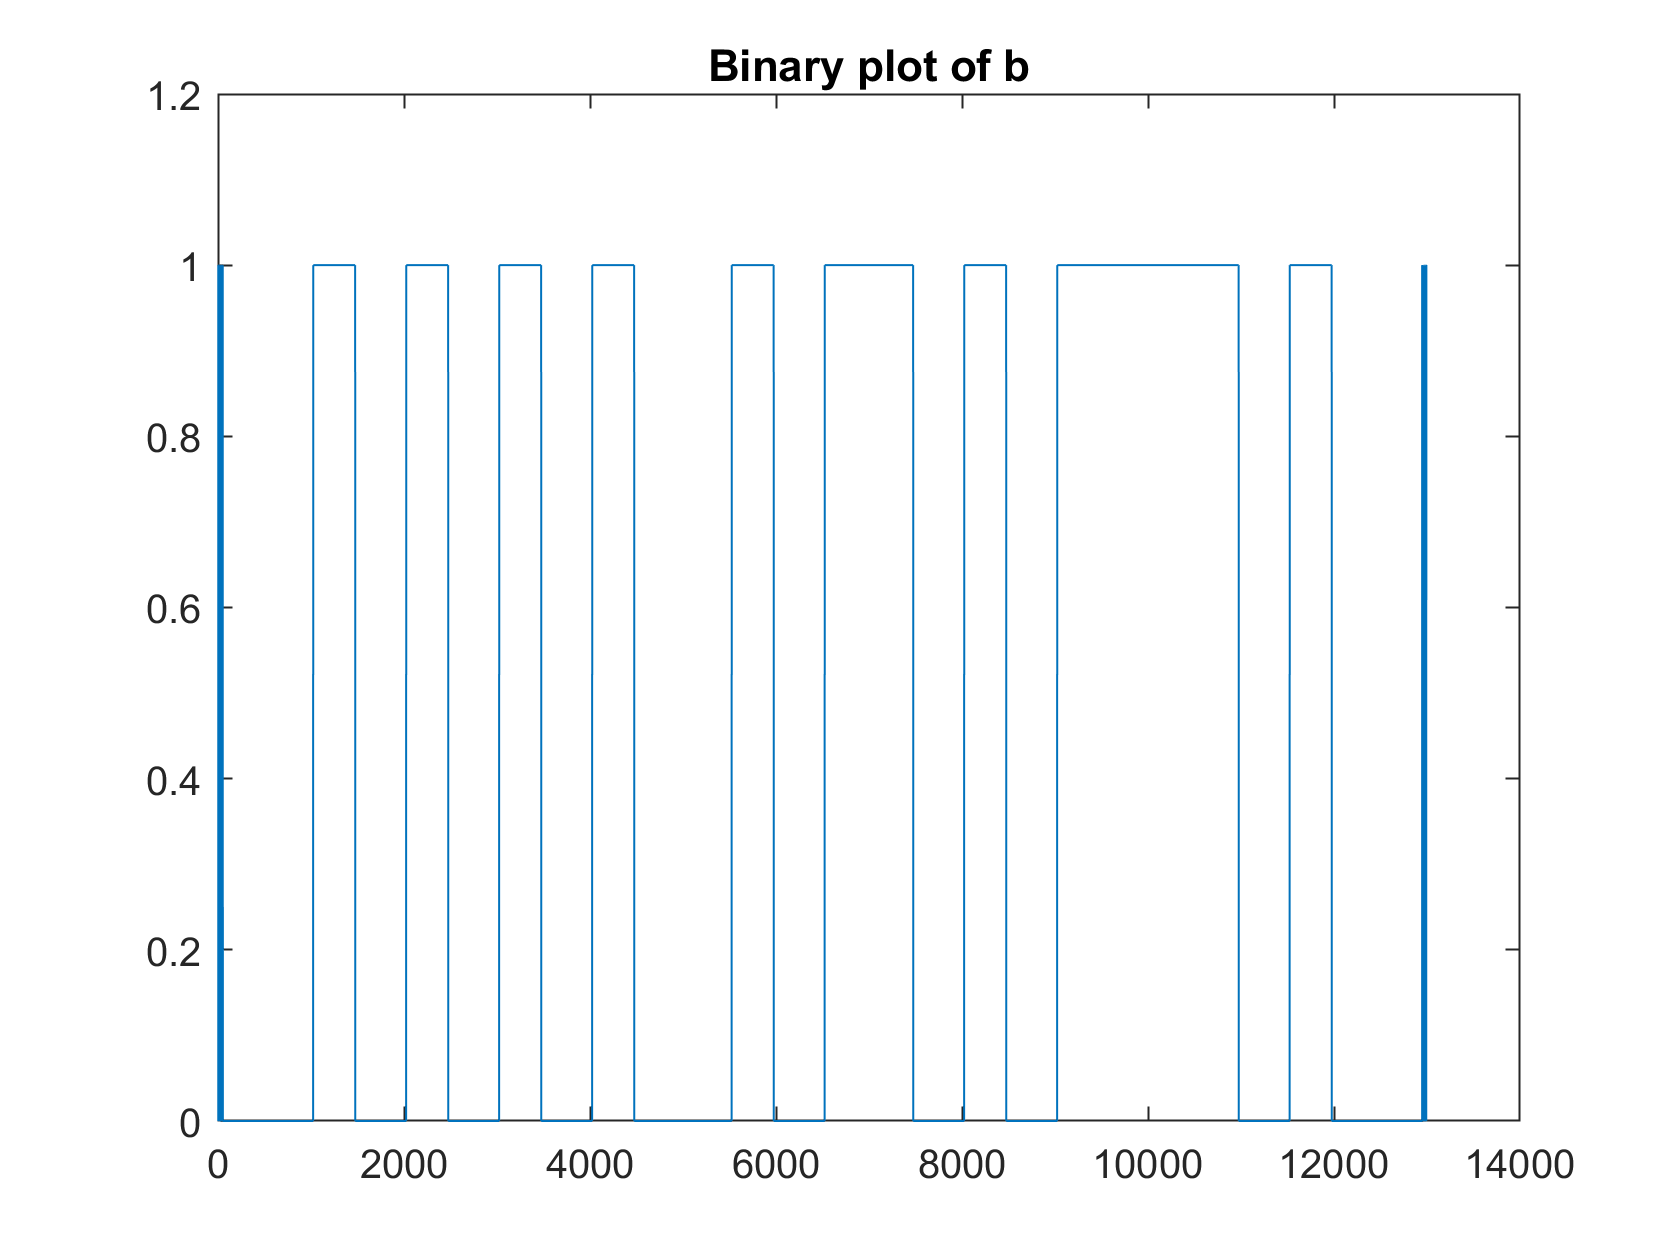

plot(bhat)
axis([0 14000 0 1.2])
title ('Binary plot of b')


%Bit Synchronization
tzero = findt0(b1, b0, gamma)

tzero = 557

[y, I] = max(b0(tzero:tzero+Ns))

y = -0.5695

I = 501

ts = I + tzero -1

ts = 1057


%Populating synch array 
synch = zeros(1,8); 
for i = 0:7
    synch(i+1) = b(ts)+(Ns*i); 
end

test = [];
for k = -1:6
    test = [test b(ts + k*Ns)];
end
test

test =    -0.6504    0.1606   -0.3948    0.1606   -0.3948    0.1606   -0.3948    0.1606



test_d = zeros(1, length(test));
for i = 1:length(test)
    if (test(i) > 0)
        test_d(i) = 1;
    elseif (test(i) == 0)
        test_d(i) = 0;
    else 
        test_d(i) = 0;
    end
end
test_d

test_d =      0     1     0     1     0     1     0     1



%Assigning Data
data = [];
for k = 7:22 %before this 0-7 are sync bits
    data = [data b(ts + k*Ns)];
end
data

data =    -0.3908   -1.1551    0.1606   -0.3948    0.1669    1.1415   -0.3948    0.1606   -0.3948    0.1669    1.1478    1.1478    1.1415   -0.3948    0.1606   -0.3803




%Now we want to convert this thing into 1's and 0's 
binary_data = zeros(1, length(data));
for i = 1:length(data)
    if (data(i) > 0)
        binary_data(i) = 1;
    elseif (data(i) == 0)
        binary_data(i) = 0;
    else 
        binary_data(i) = 0;
    end
end
binary_data

binary_data =      0     0     1     0     1     1     0     1     0     1     1     1     1     0     1     0


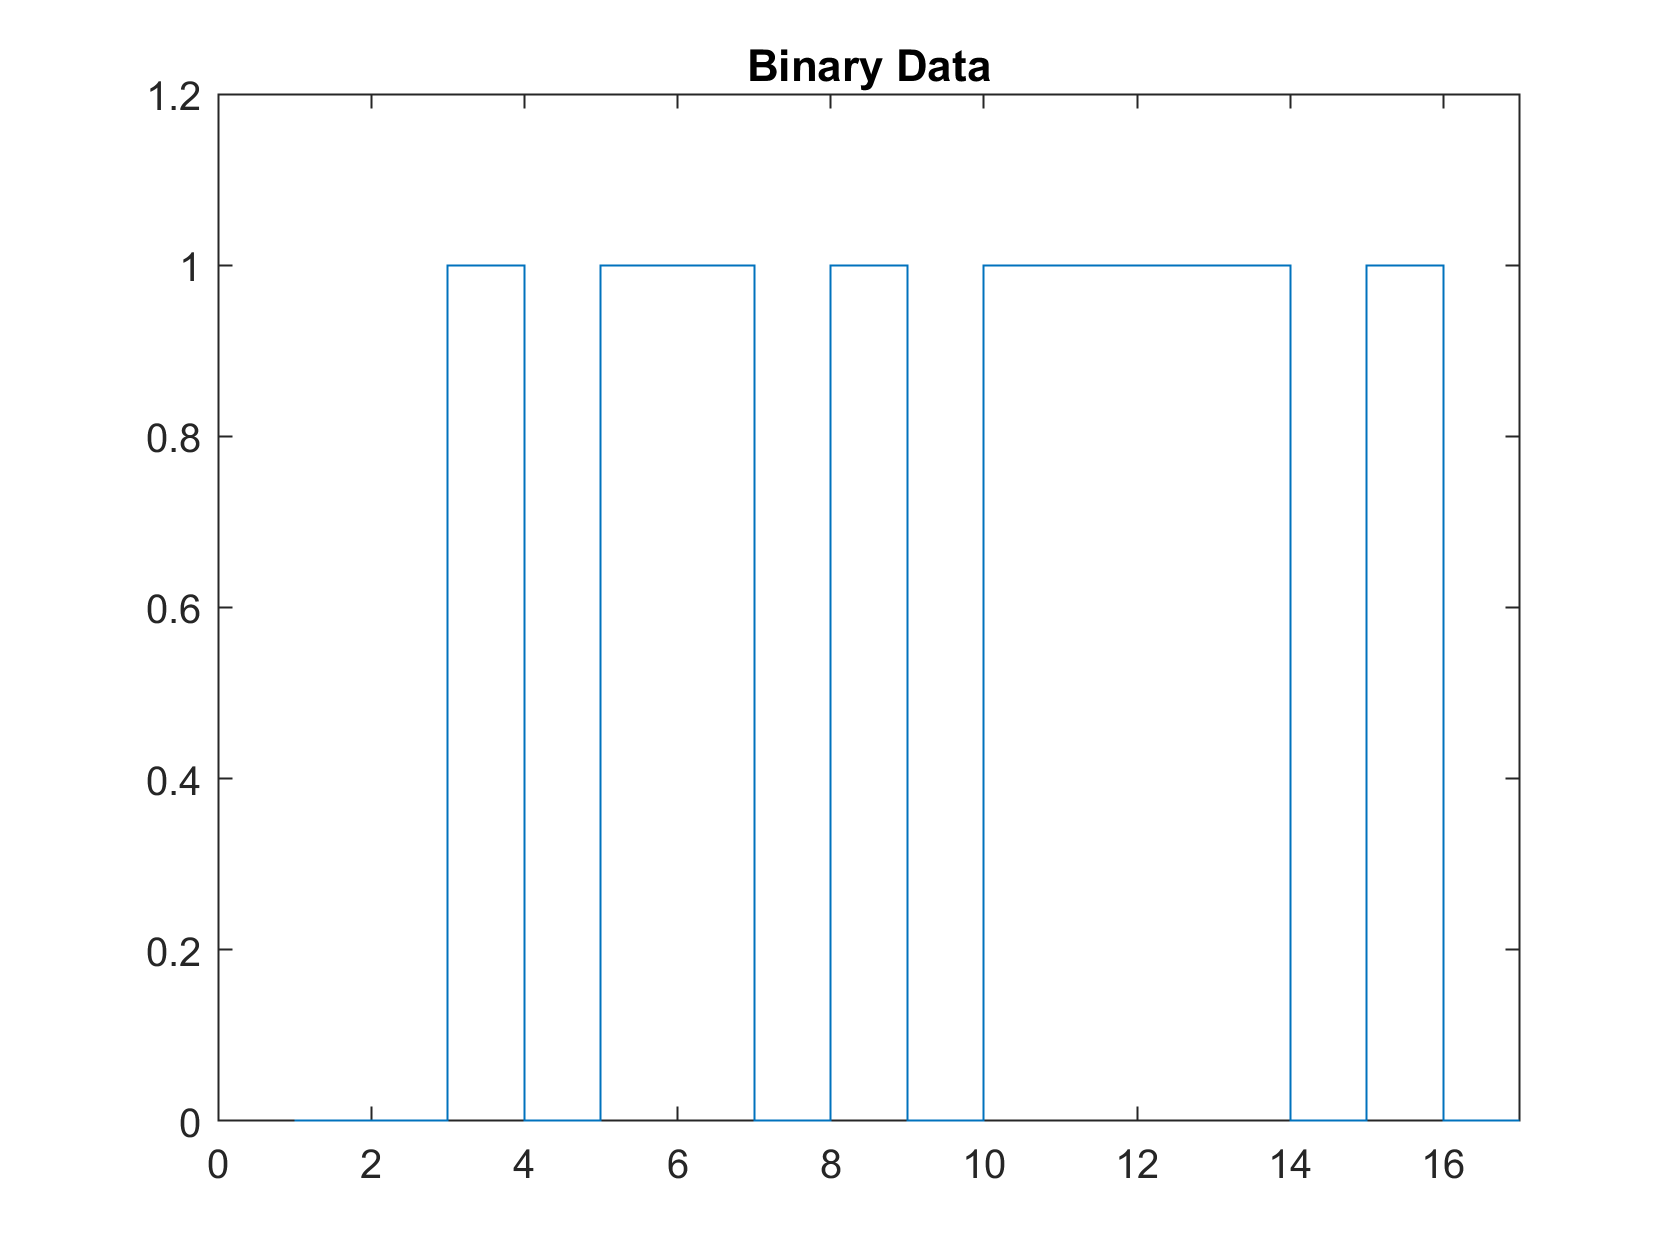

figure;
stairs([binary_data,binary_data(end)]);
axis([0 17 0 1.2])
title('Binary Data')

function t0 = findt0(b1, b0, gamma)
%Bit Synchronization
t0 = 1;
while(abs(b1(t0) + b0 (t0))< gamma)
    t0 = t0 +1; 
end
end